# Opgave 2 i "M3NUM1 F15 Ordinær eksamen"

## a)

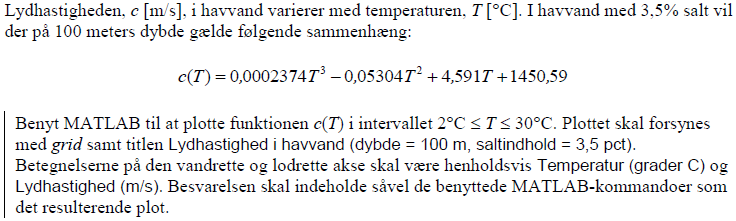

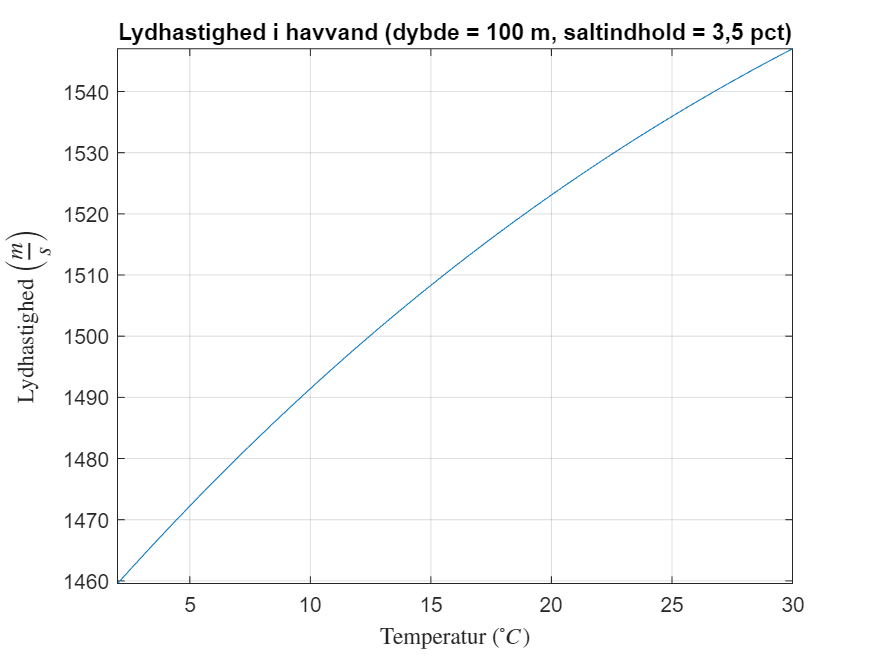

%Funktionen defineres
f = @(T) 0.0002374.*T.^3 - 0.05304.*T.^2 + 4.591.*T + 1450.59;

%temperatur intervallet der ses på
Temp = [2,30]; %degreeC 

fplot(f,Temp), grid; %Plotter funktionen i temperatur intervallet , yline(1500, "--")
%sætter titlen på plottet
title("Lydhastighed i havvand (dybde = 100 m, saltindhold = 3,5 pct)")

%sætte teksten på x-aksen
xlabel("Temperatur ($^\circ C$)",'Interpreter','latex')

%sætte teksten på y-aksen
ylabel("Lydhastighed $\left(\frac{m}{s}\right)$",'Interpreter','latex')

## b)

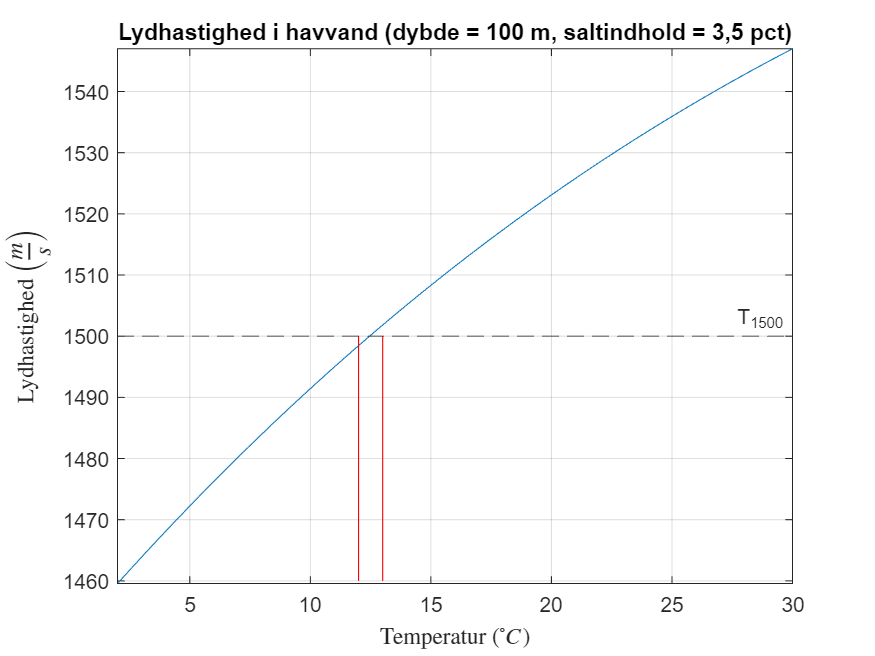

yline(1500,'--','T_{1500}'); % laver en linje ved hastigheden 1500 for bedre aflæsning
line([12 12], [1460 1500], color="r"); %aflæst resultat
line([13 13], [1460 1500], color="r"); %aflæst resultat

Temperaturen aflæses til mellem 12 og 13 og **13 vælges som svar**

## c)

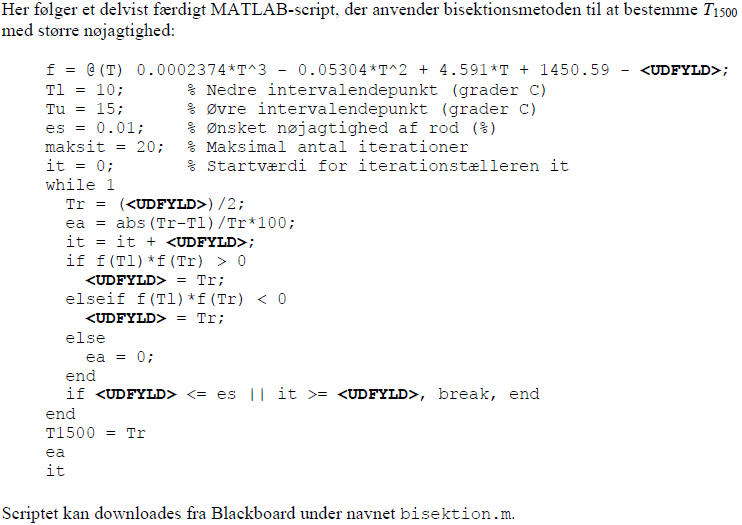

bisektion.m funktionen følger:

bisektion

T1500 = 12.4548

ea = 0.0098

it = 12

**ea** er usikkerheden

**it** er antal iterationer(forsøg)

## d)

newtraph.m funktionen følger:

syms T %laver T til et symbol
%sætter funktionen der skal undersøges denne skal sættes numersik
f = 0.0002374.*T.^3 - 0.05304.*T.^2 + 4.591.*T + 1450.59 - 1500; 

newraph(f, 15, 0.0001, 50) %kalder ligningen

root = 12.4545

ea = 1.0758e-09

iter = 4

tabel = 4×4 table
    Rod(xr)       f(xr)       df/dT (xr)    Error(ea) 
    _______    ___________    __________    __________

    12.366          8.3222        3.16          21.296
    12.454        -0.29811      3.3881         0.70649
    12.455     -0.00034229      3.3803      0.00081303
    12.455      -4.529e-10      3.3803      1.0758e-09


ans = 12.4545

## e)

% help fzero
f = @(T) 0.0002374.*T.^3 - 0.05304.*T.^2 + 4.591.*T + 1450.59 - 1500; %definer vores funktion

fzero(f,12) %finder der hvor funktionen er 0 ved at indsætte funktionen og et start gæt som her er 12

ans = 12.4545

## f)

% help roots
C = [0.0002374 -0.05304 4.591 1450.59-1500]; % array med constanterne i polynomiet
roots(C) % finder rødderne af polynomiet når konstanterne er gevet

ans = 1.0e+02 *

   1.0548 + 0.7473i
   1.0548 - 0.7473i
   0.1245 + 0.0000i


# Opgave 2 i "M3NUM1 E15 Reeksamen"

## a)

clear
f = @(x) 300 .* cos(2.*x) + x.^3 - 14 .* x.^2 - 36 .*x + 150;
x = [-8 10]

x =     -8    10


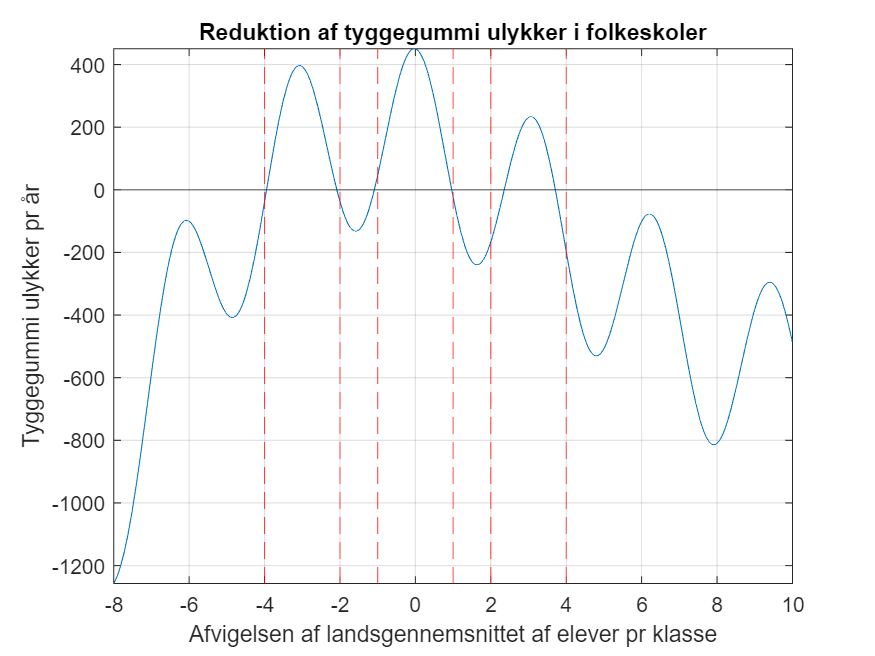

rod 1 aflæses visuelt til -4 
rod 2 aflæses visuelt til -2 
rod 3 aflæses visuelt til -1 
rod 4 aflæses visuelt til 1 
rod 5 aflæses visuelt til 2 


rod 6 aflæses visuelt til 4 


fplot(f, x), grid, yline(0) %Vi plotter funktionen og tydliggør y=0
title('Reduktion af tyggegummi ulykker i folkeskoler') 
xlabel('Afvigelsen af landsgennemsnittet af elever pr klasse')
ylabel('Tyggegummi ulykker pr år')

rod = [-4 -2 -1 1 2 4]; %Visuelt aflæste rødder skrives i en array

%laver et forloop til markering af aflæste punkter og udskriver værdien af
%disse
for i = 1:length(rod)
    xline(rod(i), '--r')
    fprintf('rod %g aflæses visuelt til %g \n', i, rod(i))
end

## b)

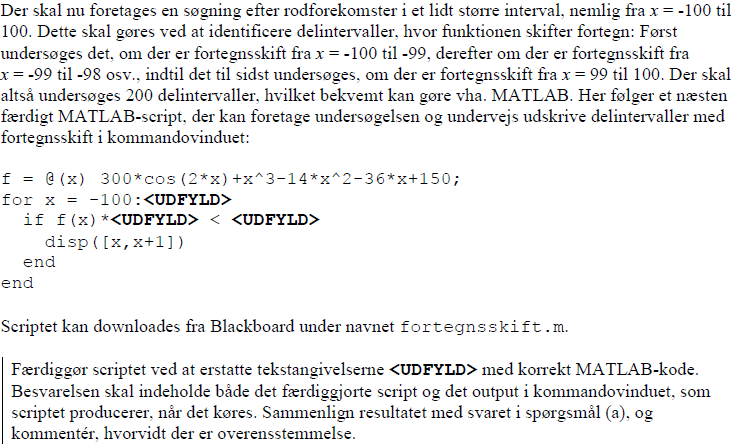

f = @(x) 300*cos(2*x)+x^3-14*x^2-36*x+150; %definer funktionen vi bruger

%starter forloop for at finde ud af hvornår vi krydser y=0
for x = -100:100 %vi leder i et intervald fra -100 til 100
    if f(x)*f(x+1) < 0 %hvis de to funktions værdier har ens fortegn vil der ikke ske noget
        disp([x,x+1]) % eller printes området hvor der er en rod.
    end
end

    -4    -3

    -3    -2

    -2    -1

     0     1

     2     3

     3     4

    15    16



## c)

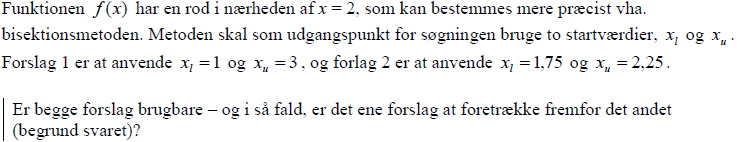

Tls = [1 1.75]

Tls =     1.0000    1.7500


Tus = [3 2.25]

Tus =     3.0000    2.2500


T1500s = []


T1500s =

     []



f = @(x) 300*cos(2*x)+x.^3-14*x.^2-36*x+150;

for i = 1:length(Tls)
    Tl = Tls(i); % Nedre intervalendepunkt (grader C)
    Tu = Tus(i); % Øvre intervalendepunkt (grader C)
    es = 0.01; % Ønsket nøjagtighed af rod (%)
    maksit = 20; % Maksimal antal iterationer
    it = 0; % Startværdi for iterationstælleren it
    while 1
        Tr = (Tl + Tu)/2; %T værdien i roden
        ea = abs(Tr - Tl)/Tr*100; %usikkerheden
        it = it + 1; %antal iterationer
        if f(Tl)*f(Tr) < 0 
            Tu = Tr; %Der sættes nyt upper limit
        elseif f(Tl)*f(Tr) > 0
            Tl = Tr; %Der sættes nyt lower limit
        else
            ea = 0; %usikkerheden er 0 da vi har ramt rigtigt
        end
        %Forloopet brydes hvis vi når et maksimalt antal forsøg eller vi kommer
        %indenfor usikkerheden.
        if ea <= es || it >= maksit
            break
        end
    end
    T1500 = Tr % Temperaturen printes
    T1500s(end + 1) = T1500
    
    

    ea % Usikkerheden printes
    it % Antal interationer der er gennemgået 
if i == length(Tls)
    break
end
    disp('---------------------------------------')
end

T1500 = 2.3551

T1500s = 2.3551

ea = 0.0052

it = 14

---------------------------------------


T1500 = 2.2499

T1500s =     2.3551    2.2499


ea = 0.0054

it = 12

x = [-8 10];
f = @(x) 300 .* cos(2.*x) + x.^3 - 14 .* x.^2 - 36 .*x + 150;
fplot(f, x), grid, yline(0); %Vi plotter funktionen og tydliggør y=0
hold on


T1 = plot(T1500s(1), f(T1500s(1)), 'or','DisplayName', 'T1500(1 til 3)')

T1 =   Line (T1500(1 til 3)) with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 2.3551
              YData: -0.0274

  Show all properties


T2 = plot(T1500s(2), f(T1500s(2)), 'ob','DisplayName', 'T1500(1.75 til 2.25)')

T2 =   Line (T1500(1.75 til 2.25)) with properties:

              Color: [0 0 1]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 2.2499
              YData: -53.7845

  Show all properties


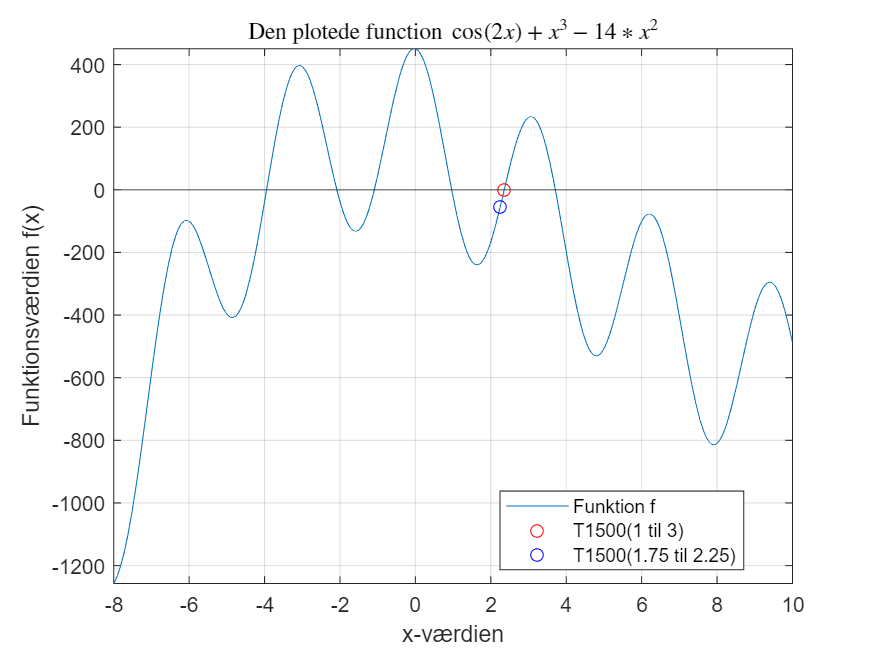

% f = @(x) 300 .* cos(2.*x) + x.^3 - 14 .* x.^2 - 36 .*x + 150;
legend('Funktion f','', 'T1500(1 til 3)', 'T1500(1.75 til 2.25)', Location='best')
title('Den plotede function $\cos(2x) + x^3 - 14 * x^2$','Interpreter','latex') 
xlabel('x-værdien')
ylabel('Funktionsværdien f(x)')
hold off